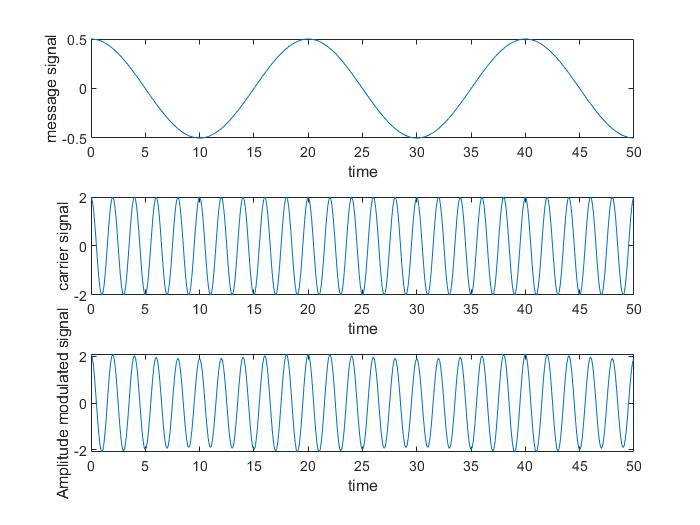

clc;
clear all;
close all;

Ac= 2; %carrier amplitude
fc= 0.5; % carrier freq (carrier freq must be at least twice message freq)
Am= .5; %message amplitude
fm= 0.05; %message signal frequency

ka1=.1; %amplitude sensitivity

t= [0:0.1:50];
ct=Ac*cos(2*pi*fc*t);
mt=Am*cos(2*pi*fm*t);
AM1= ct.*(1+ka1*mt);

subplot(3,1,1);
plot(t,mt)
xlabel("time")
ylabel("message signal")

subplot (3, 1, 2);
plot(t, ct)
ylabel("carrier signal")
xlabel("time")

subplot (3, 1, 3);
plot(t, AM1)
xlabel("time")
ylabel("Amplitude modulated signal")